This script checks how good masks fit to given images. 

% Clean up everything. 
clc;
clear;

subID = 11; % Write subject ID you want to check his/her images.

## Import files

Imgpath  = [pwd, filesep, 'images', filesep,num2str(subID), filesep];
allPics = dir([Imgpath, '*jpg']); % all pictures.

% Load images
for n = 1: length(allPics)
    rgbImages(:,:,:,n) = imread(allPics(n).name);
end

% Process images
for n = 1:length(allPics)
    hsvImages(:,:,:,n) = rgb2hsv(rgbImages(:,:,:,n)); % rgb to hsv 
    grayImages(:,:,n) = rgb2gray(rgbImages(:,:,:,n));
    masks(:,:,n) = hsvImages(:,:,1,n) > 0.005;  % color thresholding
    masks(:,:,n) = imfill(masks(:,:,n),'holes'); % fill holes. 
    gaussMasks(:,:,n) = imgaussfilt(double(masks(:,:,n)),2); % smooth mask with gaussian 
end

## Show images.

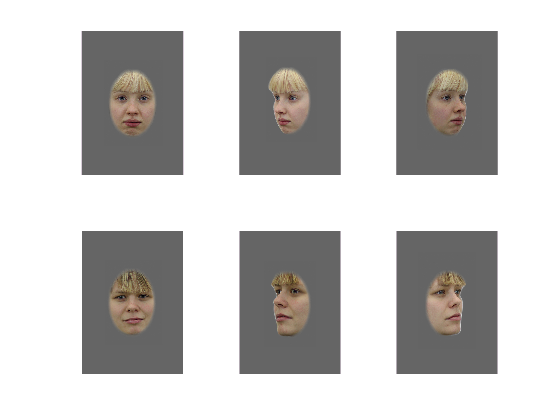

% show RGB images
figure('Name','RGB Images'); 
for n = 1: length(allPics)
    subplot(2,3,n)
    imshow(rgbImages(:,:,:,n));
end

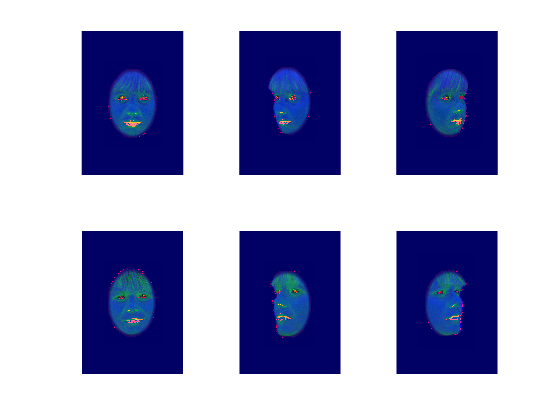

% show HSV images
figure('Name','HSV Images'); 
for n = 1: length(allPics)
    subplot(2,3,n)
    imshow(hsvImages(:,:,:,n));
end

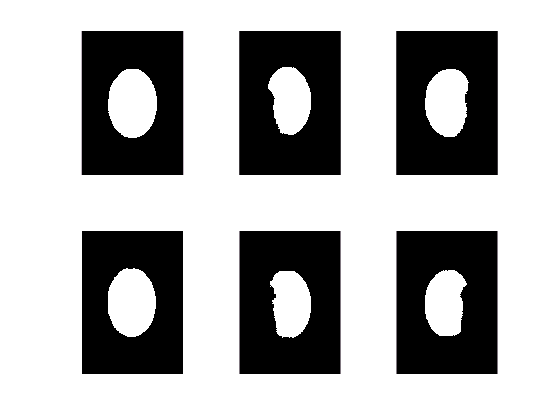

% show binary masks
figure('Name','Binary mask'); 
for n = 1: length(allPics)
    subplot(2,3,n)
    imshow(masks(:,:,n));
end

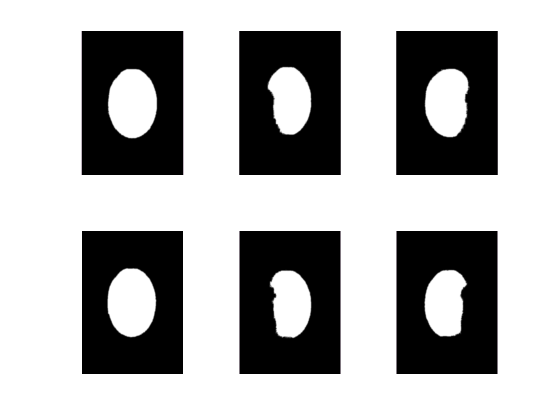

% show gaussion masks
figure('Name','Gaussian mask'); 
for n = 1: length(allPics)
    subplot(2,3,n)
    imshow(gaussMasks(:,:,n));
end

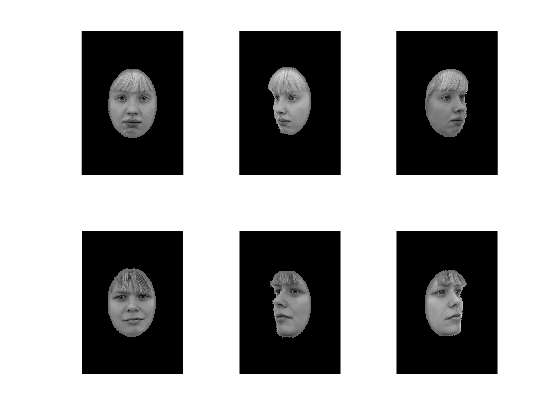

% show binary masked images
figure('Name','Binary Masked Images'); 
for n = 1: length(allPics)
    subplot(2,3,n)
    imshow(grayImages(:,:,n) .* uint8(masks(:,:,n)));
end

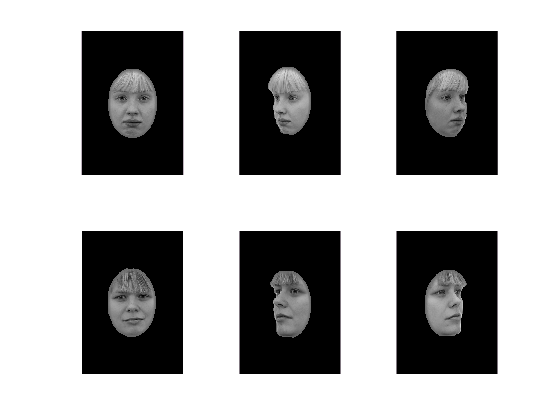

% show gaussian masked images
figure('Name','Gaussian Masked Images'); 
for n = 1: length(allPics)
    subplot(2,3,n)
    imshow(grayImages(:,:,n) .* uint8(gaussMasks(:,:,n)));
end